# Atmosphere model ISO 2533

## calculations of atmospheric parameters

% range of altitude
h = linspace(0,80000,80000);

% gravity acceleration in 0 m above sea level [m/s^2] 
g_n = 9.80665;

% earth radius [m]
R_z = 6356766;

% gravity acceleration 
g = g_n.*(R_z./(R_z+h)).^2;

% proper gas constant
R_o = 287.05287;

% range of geopotential altitude
H1 = -2:0.1:80; % [km]

% calculate temperature
T1 = zeros(1, length(H1));
for i = 1:length(H1)
    H = H1(i);
    if H < 0
        T = 301.15 - 6.5.*(H+2);
    elseif H >= 0 && H < 11
        T = 288.15 - 6.5.*(H-0);
    elseif H >= 11 && H < 20
        T = 216.65 + 0.*(H-11);
    elseif H >= 20 && H < 32
        T = 216.65 + 1.*(H-20);
    elseif H >= 32 && H < 47
        T = 228.65 + 2.8.*(H-32);
    elseif H >= 47 && H < 51
        T = 270.65 + 0.*(H-47);
    elseif H >= 51 && H < 71
        T = 270.65 - 2.8.*(H-51);
    elseif H >= 71 && H < 80
        T = 214.65 - 2.*(H-71);
    else
        T = 196.65;
    end
    T1(i) = T;
end

% calculate speed of sound
a = 20.046796.*sqrt(T1);

% multiplication of parameters by a factor to calculate pressure
g_n = g_n*1e-3;
R_o = R_o*1e-6;

% calculate pressure
p1 = zeros(1, length(H1));
for i = 1:length(H1)
    H = H1(i);
    if H < 0
        p = 127783*(1-6.5/301.15*(H+2))^(-g_n/(-6.5*R_o));
    elseif H >= 0 && H < 11
        p = 101325*(1-6.5/288.15*(H-0))^(-g_n/(-6.5*R_o));
    elseif H >= 11 && H < 20
        p = 22632*exp(-g_n/R_o/T1(i)*(H-11)); %%% T1 -> T
    elseif H >= 20 && H < 32
        p = 5474.9*(1+1/216.65*(H-20))^(-g_n/(1*R_o));
    elseif H >= 32 && H < 47
        p = 868.02*(1+2.8/228.65*(H-32))^(-g_n/(2.8*R_o));
    elseif H >= 47 && H < 51
        p = 110.91*exp(-g_n/R_o/T1(i)*(H-47)); %%% T1 -> T
    elseif H >= 51 && H < 71
        p = 66.939*(1-2.8/270.65*(H-51))^(-g_n/(-2.8*R_o));
    elseif H >= 71 && H < 80
        p = 3.9564*(1-2/214.65*(H-71))^(-g_n/(-2*R_o));
    else
        p = 0.3734;
    end
    p1(i) = p;
end

% multiplication of parameters by a factor to calculate air density
g_n = g_n*1e+3;
R_o = R_o*1e+6;

% calculate air density
rho = p1./R_o./T1;

## Plotting results

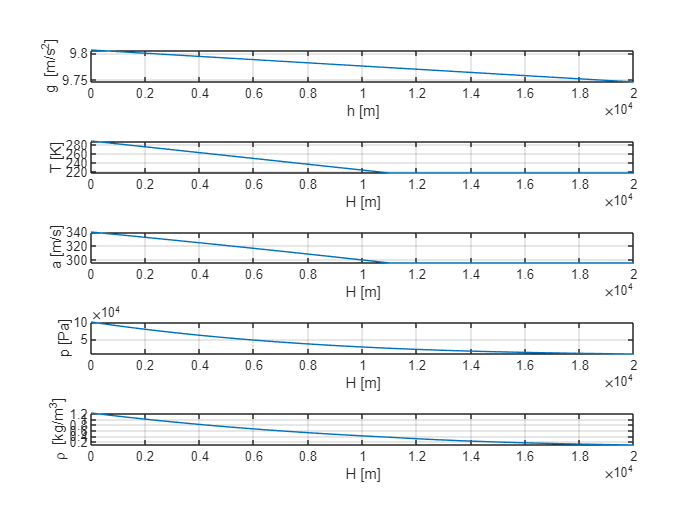


% plotting gravity acceleration 
subplot(5,1,1)
plot(h,g)
xlim([0 20000])
grid on
xlabel('h [m]')
ylabel('g [m/s^2]')


% plotting temperature
subplot(5,1,2)
plot(H1.*1000,T1)
grid on
xlabel('H [m]')
ylabel('T [K]')
axis tight
xlim([0 20000])


% plotting speed of sound
subplot(5,1,3)
plot(H1.*1000,a)
axis tight
xlim([0 20000])
grid on
xlabel('H [m]')
ylabel('a [m/s]')


% plotting pressure
subplot(5,1,4)
plot(H1.*1000,p1)
axis tight
xlim([0 20000])
grid on
xlabel('H [m]')
ylabel('p [Pa]')


% plotting air density
subplot(5,1,5)
plot(H1.*1000,rho)
axis tight
grid on
xlabel('H [m]')
ylabel('\rho [kg/m^3]')
xlim([0 20000])